# CN - L5 -  Exercici 1

Activitat d'evaluació continuada 

**Objectiu** Estudiar l’error de trucament i l’error d’arroniment de la fórmula d’ordre $\({\cal {O}}(h)\)$, definida per   

                                                                                                          
$$F(h)=\displaystyle \frac {f(x_0)-f(x_0-h)}{h}\,,\quad \quad (1)$$


 en el càlcul de la derivada de la funció $\(J_0(x)\) en \(x=2\)$ en $x=1.5$

- **Aproximeu **$\(J_0^{\prime }(1.5)\)$** fent ús de la fórmula de **$F(h)$** per a **$h_k=2^{-k}$** i **$k=1,2,\dots 6$**. Calculeu l’error absolut per cada una de les aproximacions obtingudes.**

format shortG
k=[1:6];
h=[2.^-k];
x=1.5;
valor = -besselj(1,x);
Extra = zeros(6);
errorE =  zeros(6);
for k=1:6
    k;
    hk = h(k);
    F = (besselj(0,x)-besselj(0,(x-hk)))/hk;
    ea = abs(valor - F);
    Extra(k,1) = F;
    errorE(k,1) = ea;
    if (k == 1)
        R = [hk, F, ea];
    else 
        R = [R;hk, F, ea];
    end
end

disp(array2table(R,'VariableNames',{'2^(-k)','J´(1.5)','error'}))

     2^(-k)     J´(1.5)       error  
    ________    ________    _________

         0.5    -0.50674     0.051196
        0.25    -0.53631     0.021623
       0.125    -0.54815    0.0097849
      0.0625     -0.5533    0.0046326
     0.03125    -0.55569     0.002251
    0.015625    -0.55683    0.0011091



- **Feu ús de la tècnica d'Extrapolació de Richardson **$\({\cal {O}}(h)\)$** per obtenir una aproximació de **$\(J_0^{\prime }(1.5)\)$**  amb més decimals correctes. Calculeu l’error absolut per cada una de les aproximacions obtingudes.**

iteracion=2;
for j=2:6;
    for i = iteracion:6;
        N = Extra(i,(j-1)) + (Extra(i,(j-1))-Extra(i-1,(j-1)))/((2.^(j-1))-1);
        ea = abs(valor-N);
        Extra(i,j) = N;
        errorE(i,j) = ea;
    end
    iteracion = iteracion + 1;
end

disp(array2table(Extra,'VariableNames',{'N1 = J´(1.5)', 'N2 = J´(1.5)', 'N3 = J´(1.5)', 'N4 = J´(1.5)', 'N5 = J´(1.5)','N6 = J´(1.5)'}))

    N1 = J´(1.5)    N2 = J´(1.5)    N3 = J´(1.5)    N4 = J´(1.5)    N5 = J´(1.5)    N6 = J´(1.5)
    ____________    ____________    ____________    ____________    ____________    ____________

      -0.50674               0               0               0               0               0  
      -0.53631        -0.56589               0               0               0               0  
      -0.54815        -0.55999        -0.55802               0               0               0  
       -0.5533        -0.55846        -0.55795        -0.55793               0               0  
      -0.55569        -0.55807        -0.55794        -0.55794        -0.55794               0  
      -0.55683        -0.55797        -0.55794        -0.55794        -0.55794        -0.55794  



disp(array2table(errorE,'VariableNames',{'N1 = J´(1.5) (error)', 'N2 = J´(1.5) (error)', 'N3 = J´(1.5) (error)', 'N4 = J´(1.5) (error)', 'N5 = J´(1.5) (error)','N6 = J´(1.5) (error)'}))

    N1 = J´(1.5) (error)    N2 = J´(1.5) (error)    N3 = J´(1.5) (error)    N4 = J´(1.5) (error)    N5 = J´(1.5) (error)    N6 = J´(1.5) (error)
    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________

          0.051196                        0                       0                       0                       0                      0      
          0.021623                0.0079508                       0                       0                       0                      0      
         0.0097849                 0.002053               8.704e-05                       0                       0                      0      
         0.0046326               0.00051971              8.6201e-06   

- **Presenteu els resultats dels dos apartats previs en una mateixa taula (T1).**

T1=table(R,Extra,errorE)

T1 = 6×3 table
                    R                        Extra           errorE   
    __________________________________    ____________    ____________

         0.5     -0.50674     0.051196    [1×6 double]    [1×6 double]
        0.25     -0.53631     0.021623    [1×6 double]    [1×6 double]
       0.125     -0.54815    0.0097849    [1×6 double]    [1×6 double]
      0.0625      -0.5533    0.0046326    [1×6 double]    [1×6 double]
     0.03125     -0.55569     0.002251    [1×6 double]    [1×6 double]
    0.015625     -0.55683    0.0011091    [1×6 double]    [1×6 double]


- **Representeu els decimals correctes en una gràfica amb **$\(k=1,2,\dots 6\)$** a l’eix d’abscises. Quantes xifres decimals correctes s’obtenen en cada cas? Argumenta la teva resposta.**

La preicisió d'una amplia gama de métodes numèrics (com la derivació en aquest cas) per aproximar iterativament un valor concret depèn del tamany del pas **h. **En general, reduir h provocará l'augment de l'ordre de l'error de truncament del resultat. Teóricament, el valor exacte que volem calcular el podríem obtenir quan h tendeix a 0. Gràcies a l'extrapolació de Richardson podem accelerar el procés d'obtenció d'una millor estimació de la derivada ja que es un mètode que redueix progresivament h (tamany del pas) i en conseqüència augmenta l'ordre d'error de truncament. 

decimals_correctes = [h',tril(fix(-log10(2*errorE)))];
disp(array2table(decimals_correctes,'VariableNames',{'2^-k','N1 = J´(1.5) (decimals correctes)', 'N2 = J´(1.5) (decimals correctes)', 'N3 = J´(1.5) (decimals correctes)', 'N4 = J´(1.5) (decimals correctes)', 'N5 = J´(1.5) (decimals correctes)','N6 = J´(1.5) (decimals correctes)'}))

      2^-k      N1 = J´(1.5) (decimals correctes)    N2 = J´(1.5) (decimals correctes)    N3 = J´(1.5) (decimals correctes)    N4 = J´(1.5) (decimals correctes)    N5 = J´(1.5) (decimals correctes)    N6 = J´(1.5) (decimals correctes)
    ________    _________________________________    _________________________________    _________________________________    _________________________________    _________________________________    _________________________________

         0.5                    0                                    0                                    0                                    0                                    0                                    0                
        0.25                    1                       

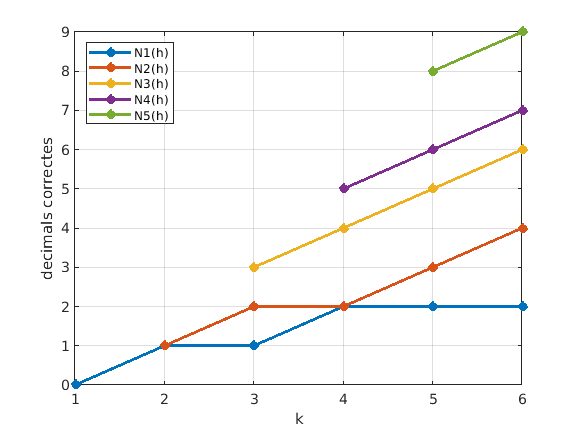

k = [1:6]';
p=plot(k,decimals_correctes(:,2),'-o',"LineWidth",2);
p.MarkerFaceColor = p.Color;
hold on
p=plot(k(2:6),decimals_correctes(2:6,3),'-o',"LineWidth",2);
p.MarkerFaceColor = p.Color;
p=plot(k(3:6),decimals_correctes(3:6,4),'-o',"LineWidth",2);
p.MarkerFaceColor = p.Color;
p=plot(k(4:6),decimals_correctes(4:6,5),'-o',"LineWidth",2);
p.MarkerFaceColor = p.Color;
p=plot(k(5:6),decimals_correctes(5:6,6),'-o',"LineWidth",2);
p.MarkerFaceColor = p.Color;
hold off
grid on 
ylabel('decimals correctes')
xlabel('k') 
legend({'N1(h)','N2(h)','N3(h)','N4(h)','N5(h)'},"Location","northwest")